# Creating a WirelessNetwork Object

We begin by creating a `WirelessNetwork` object and assign it to `net`, which is the name of the variable that describes our network.

net = WirelessNetwork

net =   WirelessNetwork with properties:

           bs_locations: []
            bs_channels: []
           bs_power_dBm: []
           channel_sets: []
    sector_offset_angle: 0
         map_resolution: 250
              noise_dBm: -100
            pl_exponent: 3
            SINR_thresh: 10
         ms_per_channel: 10
              max_users: []
           map_filename: 'Morgantown'
          save_filename: 'MyProject'
                   cost: []


# Managing Channels

We have purchased the licenses to 20 RF channels. Moreover, suppose that we do not plan to use sectorization (see the other example for sectorization) and that we would like to have 4 channel sets (think of this as clusters of size N=4).   Because 20 is divisible by 4, each station can have the same number of channels.

We can specify our channel sets as a vector containing four 5s.

net.channel_sets = [5 5 5 5]

net =   WirelessNetwork with properties:

           bs_locations: []
            bs_channels: []
           bs_power_dBm: []
           channel_sets: [5 5 5 5]
    sector_offset_angle: 0
         map_resolution: 250
              noise_dBm: -100
            pl_exponent: 3
            SINR_thresh: 10
         ms_per_channel: 10
              max_users: []
           map_filename: 'Morgantown'
          save_filename: 'MyProject'
                   cost: []


This verifies that the total number of channels in the channel set does not exceeed the number of channels we are purchasing.

total_channels = sum(net.channel_sets)

total_channels = 20

# Estimating the Number of Base Stations

Before we start placing our base stations, we need to estimate how many we can afford.  As described in WirelessProjectPart1.mlx, each base station has a fixed cost of $250,000 (meant to include the cost of the property it is located on, the tower struture, and the networking/power resources provided to it) plus $25,000 per RF channel's transciever (meant to be the cost of the radio equipment).   Because our channel sets all use 5 channels, the cost of each base station is 250+5*25=$375,000.   

Suppose our total budget is $20,000,000.  We have licensed 20 RF channels, which cost $500,000 each.  Thus the cost of our spectrum licenses is 24*500 = $10,000,000.  Given our overall budget, this leaves $10,000,000 for base stations.  We can afford 10000/375 = 26.67 base stations. We will have to round down and only buy 26 base stations to remain within our budget.

# Adding the First Cluster of Base Stations

We used a hexagonal structure of base stations with a cluster size N=4. This works well with our channel set being evenly divided four ways.

net.CreateCentralCluster(4,0)

ans =   WirelessNetwork with properties:

           bs_locations: [4×1 double]
            bs_channels: [4×1 double]
           bs_power_dBm: [4×1 double]
           channel_sets: [5 5 5 5]
    sector_offset_angle: 0
         map_resolution: 250
              noise_dBm: -100
            pl_exponent: 3
            SINR_thresh: 10
         ms_per_channel: 10
              max_users: []
           map_filename: 'Morgantown'
          save_filename: 'MyProject'
                   cost: []


bs_power_dBm = 30 * ones(28,1)

bs_power_dBm =     30
    30
    30
    30
    30
    30
    30
    30
    30
    30
    30
    30
    30
    30
    30


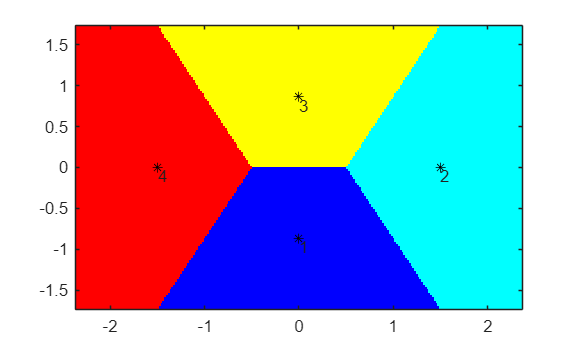

net.SetPower(bs_power_dBm)
net.MapCoverage

# Adding the First Layer of Interferance

We used the provided methods to provide the first layer of interferance for our network and automate the placement of base stations around the center of the map. This creates a total of 28 base stations, which puts us over budget because we can only afford 26 base stations. This issue is resolved in a later step.

net.CreateFirstTier(4)

ans =   WirelessNetwork with properties:

           bs_locations: [28×1 double]
            bs_channels: [28×1 double]
           bs_power_dBm: [28×1 double]
           channel_sets: [5 5 5 5]
    sector_offset_angle: 0
         map_resolution: 250
              noise_dBm: -100
            pl_exponent: 3
            SINR_thresh: 10
         ms_per_channel: 10
              max_users: []
           map_filename: 'Morgantown'
          save_filename: 'MyProject'
                   cost: []


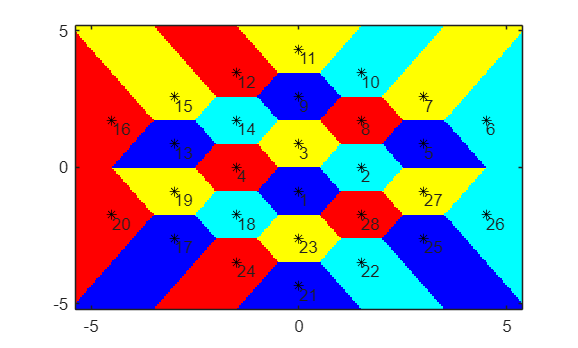

net.SetPower(bs_power_dBm)
net.MapCoverage

# Centering Network on Map

To match the map coordinates, we resized and moved our entire network structure so that it was centered in the middle of the city map.

bs_expanded = 60*net.bs_locations;
bs_shift = bs_expanded + 300 + 300*1i;
net.bs_locations = bs_shift;

# Removing Base Stations

We need to create a network containing 26 base stations to remain within budget. To do this, we need to remove two base stations from our network. We made the decision to remove base station 26 and base station 16. We made this decision by looking at the network coverage map and the map of attempted calls at 19:00, the busiest hour of the day. Through visual examination, we came to the conclusion that the fewest number of callers would be affected by the removal of those two stations.

Let's look at the net object to verify that it has 26 base stations:

net.RemoveBase(26)
net.RemoveBase(16)

net

net =   WirelessNetwork with properties:

           bs_locations: [26×1 double]
            bs_channels: [26×1 double]
           bs_power_dBm: [26×1 double]
           channel_sets: [5 5 5 5]
    sector_offset_angle: 0
         map_resolution: 250
              noise_dBm: -100
            pl_exponent: 3
            SINR_thresh: 10
         ms_per_channel: 10
              max_users: []
           map_filename: 'Morgantown'
          save_filename: 'MyProject'
                   cost: []


# Analyzing the Network

## Coverage Map

This generates a map of the areas covered by each base station.

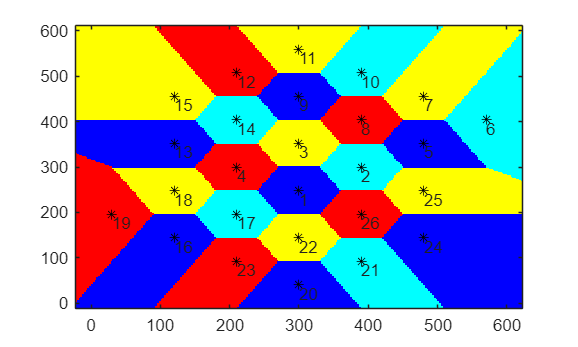

net.MapCoverage

## SINR Outage Map

This generates a map of the areas that meet the minimum SINR requirement for users to be connected to the network.

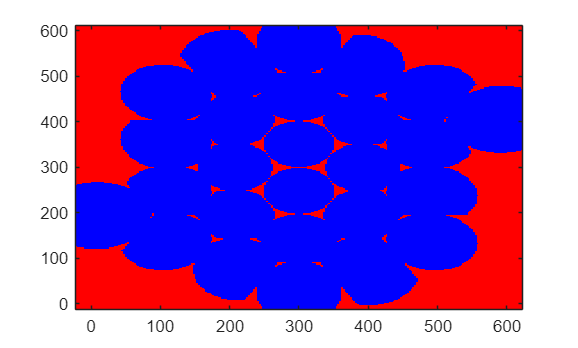

Covering 69.21 percent of the area with sufficient SINR
worst case SINR is 0.745888


net.MapSINR

## City Map with Mobiles at 19:00 Superimposed

This generates a city map of all the users within the city at 19:00, the hour with the highest volume of network traffic. Blue dots indicate users that meet the minimum SINR requirements to be covered by the network. Red dots indicate users that do not meet the minimum SINR requirements to be covered by the network.

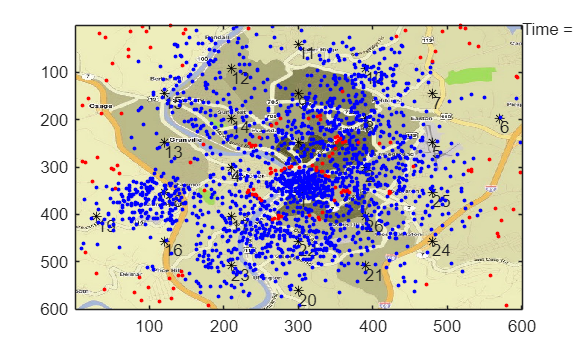

ans = struct with fields:
       cdata: [344×543×3 uint8]
    colormap: []


net.MapCity( ms_locations{19} )

## Coverage Map with Mobiles at 19:00 Superimposed

This generates a coverage map of all the users within the within the city at 19:00, the hour with the highest volume of network traffic. Black dots indicate users that meet the minimum SINR requirements to be covered by the network. Black crosses indicate users that do not meet the minimum SINR requirements to be covered by the network.

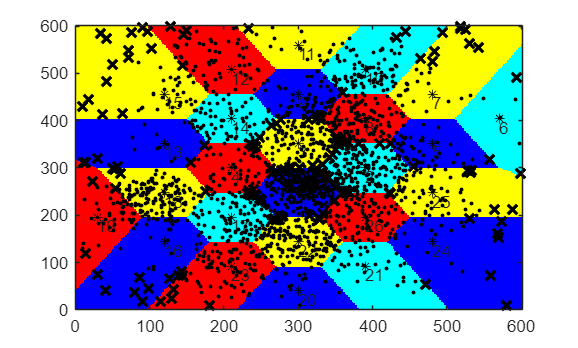

ans = struct with fields:
       cdata: [344×543×3 uint8]
    colormap: []


net.MapMobiles( ms_locations{19} )

## Connected Users, Call Attempts, and Number Over Threshold by Hour

This plots the number of attempted calls per hour, along with the number of those calls that is covered by the network and the number of those calls that is connected to the network.

[num_connected, num_over_thresh] = net.AnalyzeNetwork( ms_locations )

num_connected =          440         363         275         182         227         391         523         691         850         805         793         929         964         872         868         898         971         971        1012         980         924         826         731         608


num_over_thresh =          455         377         275         182         227         419         564         833        1154        1021        1022        1483        1577        1304        1251        1335        1624        1669        1852        1719        1476        1149         923         686


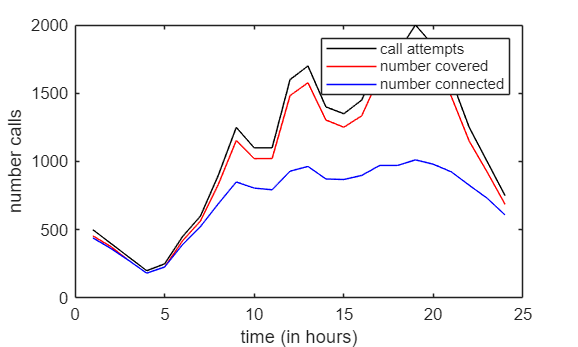

plot( 1:length(call_attempts), call_attempts, '-k', ...
    1:length(call_attempts), num_over_thresh, '-r', ...
    1:length(call_attempts), num_connected, '-b' );
xlabel( 'time (in hours)' );
ylabel( 'number calls' );
legend( 'call attempts', 'number covered', 'number connected' );

## Connected and Covered Users by Hour

This plots the fraction of attempted calls that are covered by the network, along with the fraction of attempted calls that are connected to the network.

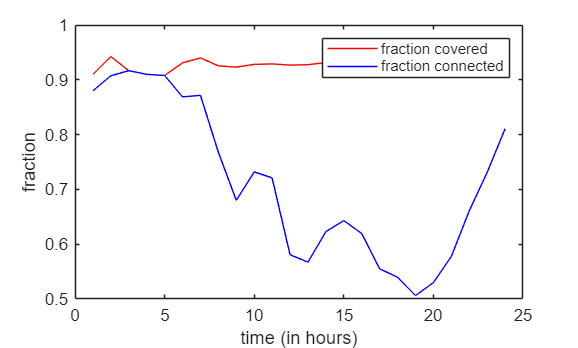

fraction_over_thresh = num_over_thresh./call_attempts;
fraction_connected = num_connected./call_attempts;
plot( 1:length(call_attempts), fraction_over_thresh, '-r', ...
    1:length(call_attempts), fraction_connected, '-b');
xlabel( 'time (in hours)' );
ylabel( 'fraction' );
legend( 'fraction covered', 'fraction connected');

## Network Cost in Dollars

This computes the cost of the network in tens of thousands of dollars.

net.ComputeCost

ans = 19750

actual_cost = net.ComputeCost * 1000

actual_cost = 19750000

fprintf( 'The cost of the network is $%10.2f\n', actual_cost)

The cost of the network is $19750000.00


## Total Number of Connected Users

This computes the total number of calls that were successfully connected to the network over the span of a day.

sum(num_connected)

ans = 17094

## Total Number of Call Attempts

This computes the total number of attempted calls made on the network over the span of a day.

sum( call_attempts )

ans = 26550

## Total Percentage of Users Connected

This computes the percentage of attempted calls that were successfully connected to the network over the span of a day.

percent_connected = sum(num_connected)/sum(call_attempts);
fprintf( 'The percentage connected is %2.2f%%\n', 100*percent_connected)

The percentage connected is 64.38%


# Preliminary Network Draft

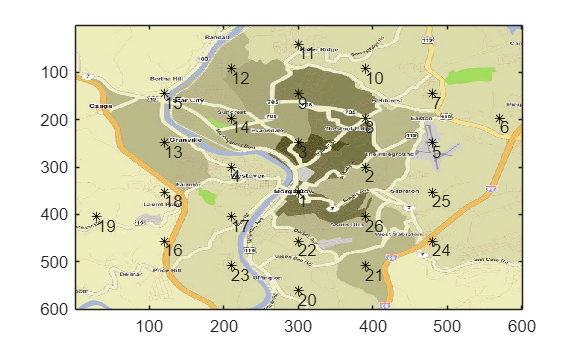

ans = struct with fields:
       cdata: [344×543×3 uint8]
    colormap: []


net.MapCity

# Saving the Network

This saves our network file as "UnitedPacketServicePreliminary.mat"

net.Save( "UnitedPacketServicePreliminary.mat")